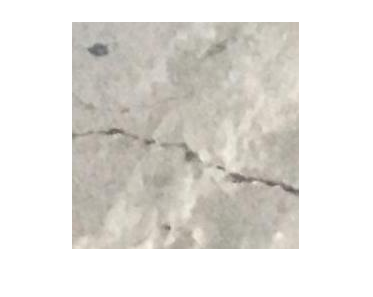

% img = imread("../../data/data/Concrete Crack Images/00165.jpg");
% img = imread("../../data/data/Concrete Crack Images/00166.jpg");
imgRef = imread("../../data/data/Concrete Crack Images/00166.jpg");
img = imread("../../data/data/Concrete Crack Images/00051.jpg");
imshow(img)

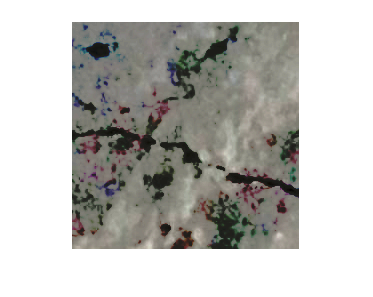

img = imhistmatch(img,imgRef);
imshow(img)

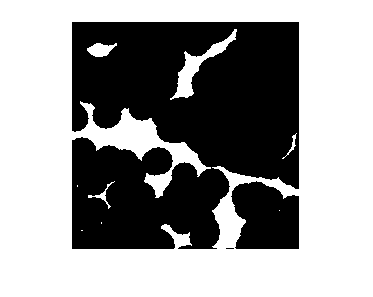

res = extractCrack(img);
imshow(res.BW)

BW = res.BW;


% 作成 results.Area の histogram
h = histogram(results.Area,"NumBins",20,"DisplayName","Area");

名前 'results.Area' を解決できません。


% xlabel および title の追加
xlabel("Area")
title("Area")
legend

imagesFolder = fullfile(toolboxdir("nnet"),"nndemos","nndatasets","DigitDataset");
imds = imageDatastore(imagesFolder,"IncludeSubfolders",true,"LabelSource","foldernames")

imds =   ImageDatastore のプロパティ:

                       Files: {
                              ' ...\R2022b\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image10000.png';
                              ' ...\R2022b\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9001.png';
                              ' ...\R2022b\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9002.png'
                               ... and 9997 more
                              }
                     Folders: {
                              ' ...\MATLAB\R2022b\toolbox\nnet\nndemos\nndatasets\DigitDataset'
                              }
                      Labels: [0; 0; 0 ... and 9997 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDat

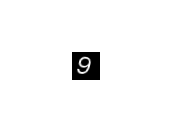

idx = 9017;
[img, imgInfo] = readimage(imds,idx);
imshow(img)

imgBW = imbinarize(img);
props = regionprops("table",imgBW,"Orientation")

props = table
    Orientation
    ___________

      70.839   


imagesFolder = fullfile(toolboxdir("nnet"),"nndemos","nndatasets","DigitDataset");
imds = imageDatastore(imagesFolder,"IncludeSubfolders",true,"LabelSource","foldernames")

imds =   ImageDatastore のプロパティ:

                       Files: {
                              ' ...\R2022b\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image10000.png';
                              ' ...\R2022b\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9001.png';
                              ' ...\R2022b\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9002.png'
                               ... and 9997 more
                              }
                     Folders: {
                              ' ...\MATLAB\R2022b\toolbox\nnet\nndemos\nndatasets\DigitDataset'
                              }
                      Labels: [0; 0; 0 ... and 9997 more categorical]
    AlternateFileSystemRoots: {}
                    ReadSize: 1
      SupportedOutputFormats: ["png"    "jpg"    "jpeg"    "tif"    "tiff"]
         DefaultOutputFormat: "png"
                     ReadFcn: @readDat


Image = [];
Label = [];
Angle = [];

while hasdata(imds)
    [img, imgInfo] = read(imds);
    imgInfo;
    imgBW = imbinarize(img);
    props = regionprops("table",imgBW,"Orientation");

    if height(props) == 1
        Image = [Image; string(imgInfo.Filename)];
        Label = [Label; imgInfo.Label];
        Angle = [Angle; props.Orientation];
    end
%     imshow(img)
end

digitData = table(Image,Label,Angle)

digitData = 8954×3 table
                                                Image                                                 Label     Angle 
    ______________________________________________________________________________________________    _____    _______

    "C:\Program Files\MATLAB\R2022b\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image10000.png"      0       6.7263
    "C:\Program Files\MATLAB\R2022b\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9001.png"       0       82.052
    "C:\Program Files\MATLAB\R2022b\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9002.png"       0      -44.263
    "C:\Program Files\MATLAB\R2022b\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9003.png"       0       78.965
    "C:\Program Files\MATLAB\R2022b\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9004.png"       0       70.774
    "C:\Program Files\MATLAB\R2022b\toolbox\nnet\nndemos\nndatasets\DigitDataset\0\image9005.png"       0       87.527
    "C:\Program Files\